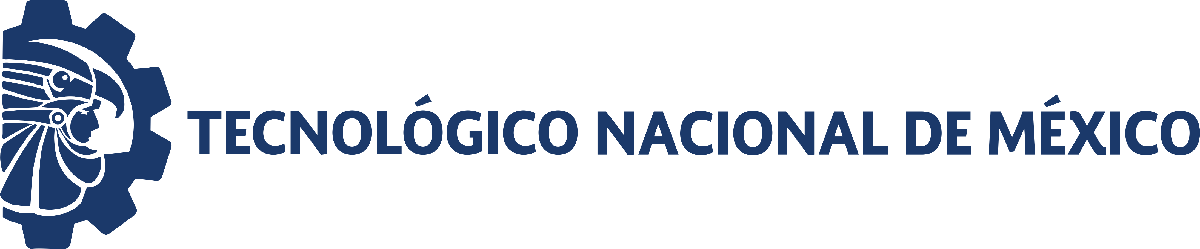                                 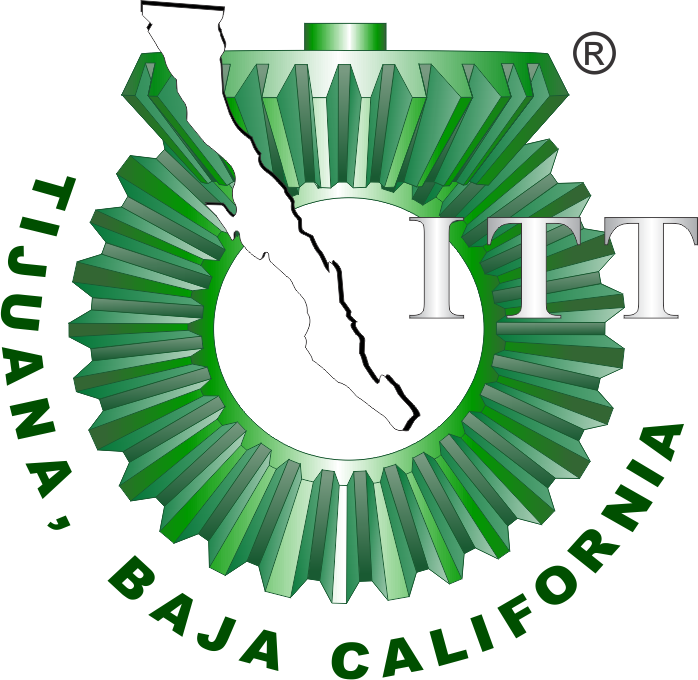

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

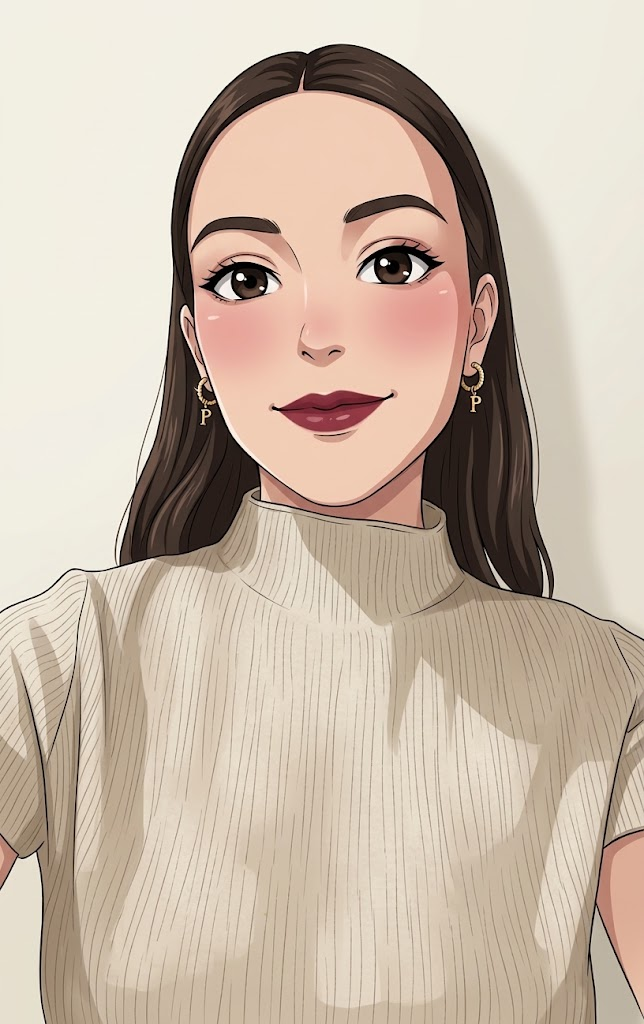

Nombre del alumno: Vanessa Yamileth Suarez Ceja

Número de control: 23212236

Correo institucional: L23212236**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemaP3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Respuesta al impulso unitario

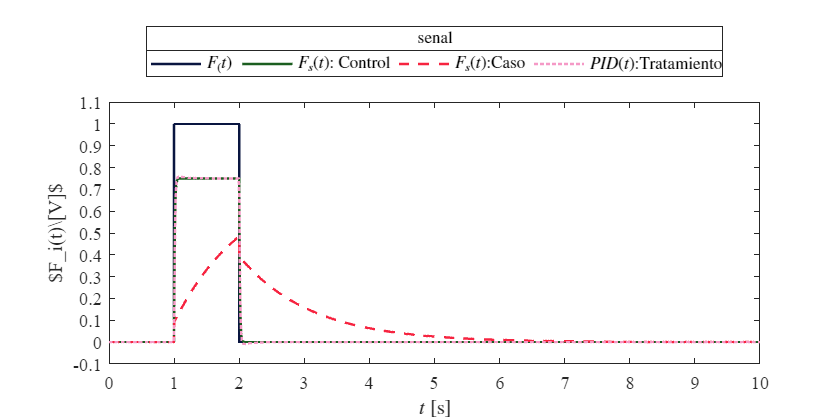

X = sim(file, parameters);
plotsignals(X.t,X.F,X.Fsx,X.Fsy,X.PID, 'senal')

## **Función: Respuesta de la simulación **

function plotsignals(t,F,Fsx,Fsy,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [9,21,64]/255;
    clr2 = [27,94,32]/255;
    clr3 = [246,36,64]/255;
    clr4 = [245,153,198]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',...
        t,PID,':', 'lineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e2:length(t));
    
    L = legend('$F_(t)$','$F_{s}(t)$: Control','$F_{s}(t)$:Caso','$PID(t)$:Tratamiento');

    set(L,'interpreter','latex','location','northoutside','orientation','Horizontal')
    title(L,[signal])

    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$F_i(t)\[V]$','Interpreter','latex')

    xlim([0 10]); xticks(0:1:15)

    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end